Read image

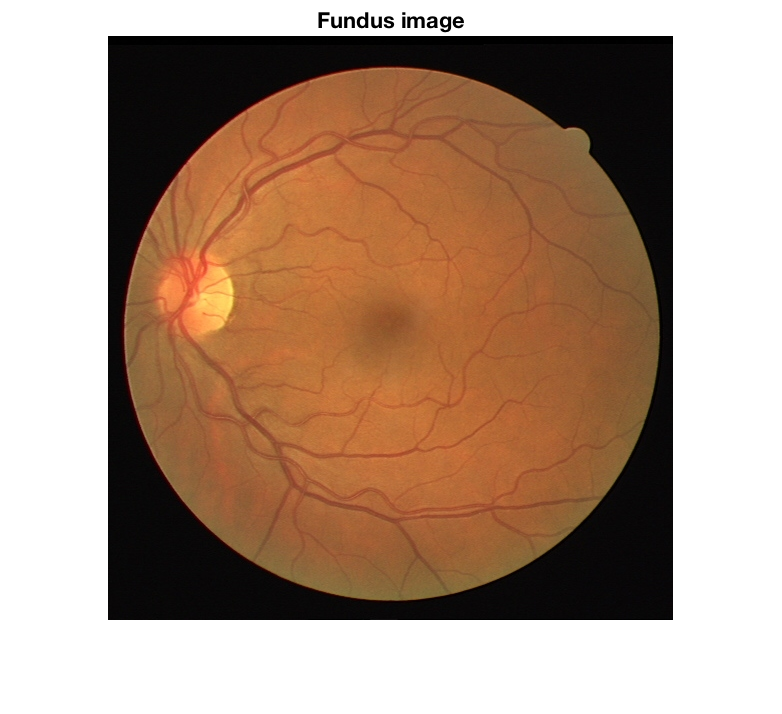

im = imread('../dataset/DRIVE/test/images/01_test.tif');
imshow(im)
title('Fundus image')

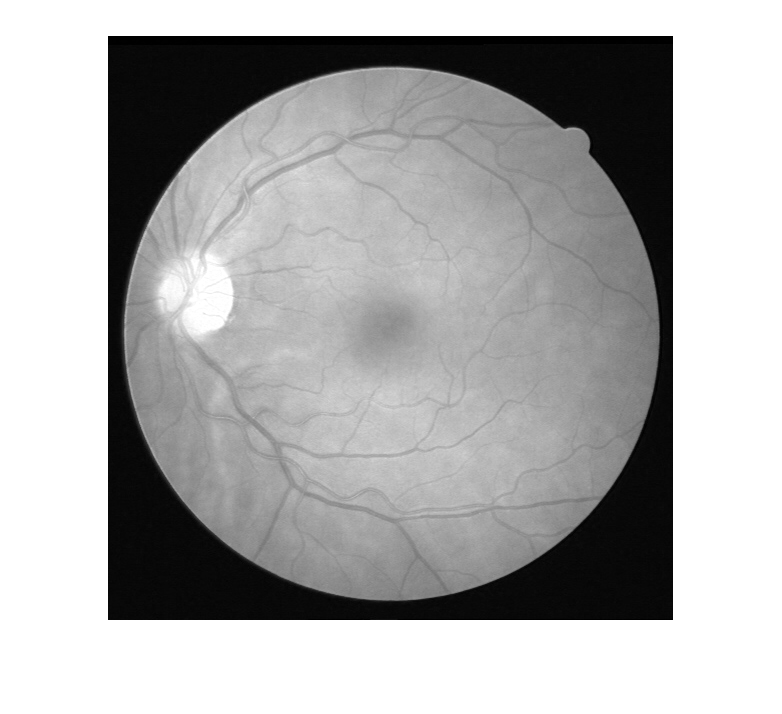


imshow(im(:,:,1));

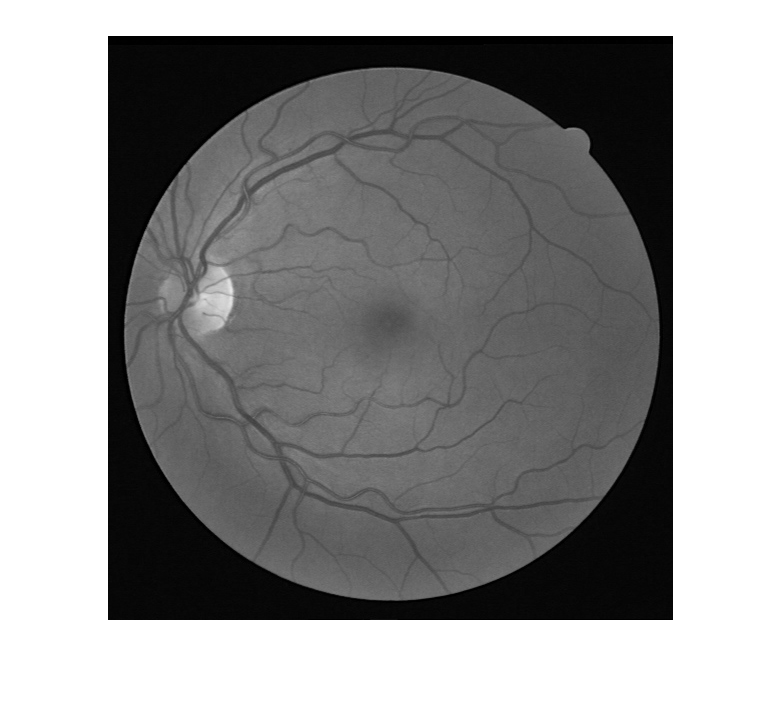

imshow(im(:,:,2));

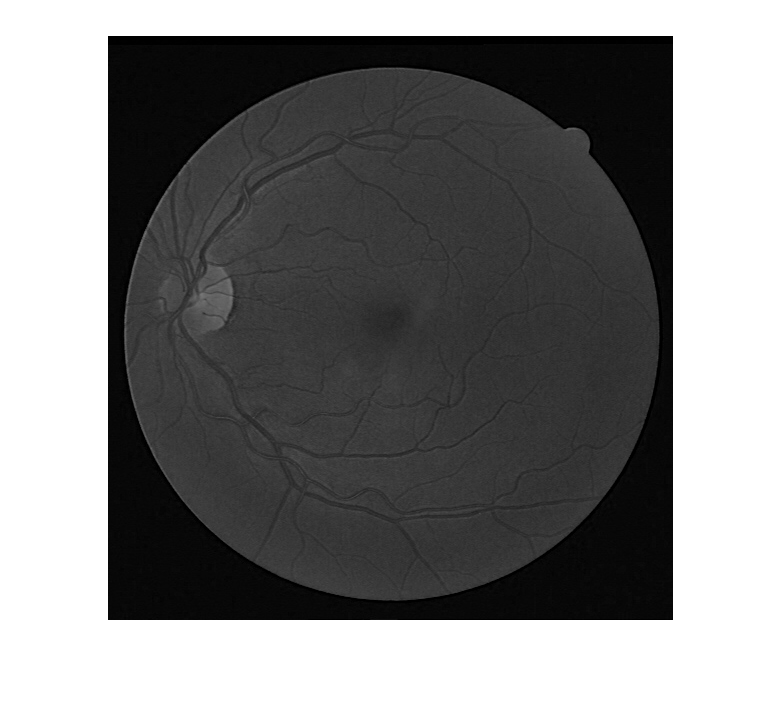

imshow(im(:,:,3));

Extract green channel

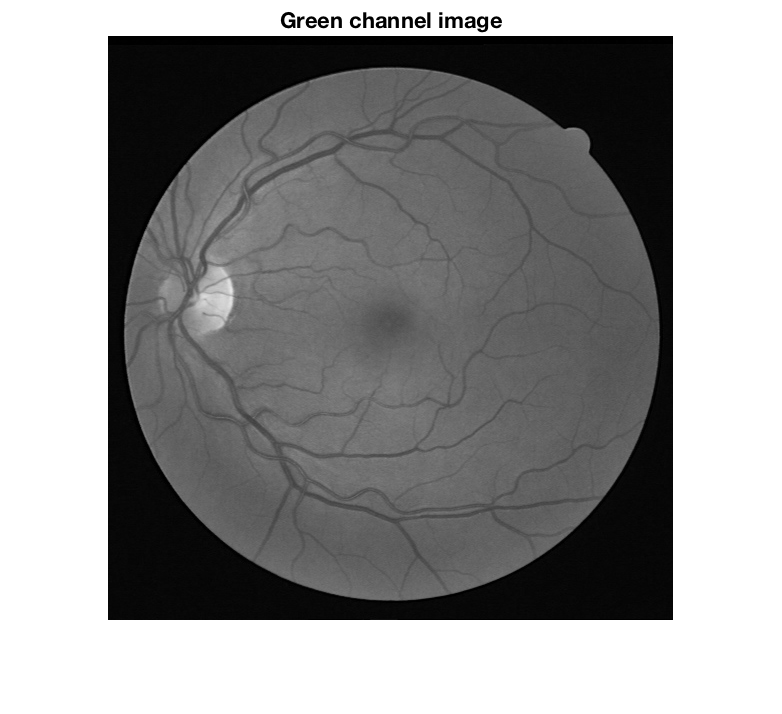

green = im(:,:,2);
imshow(green)
title('Green channel image')

Contrast-Limited Adaptive Histogram Equalization filter

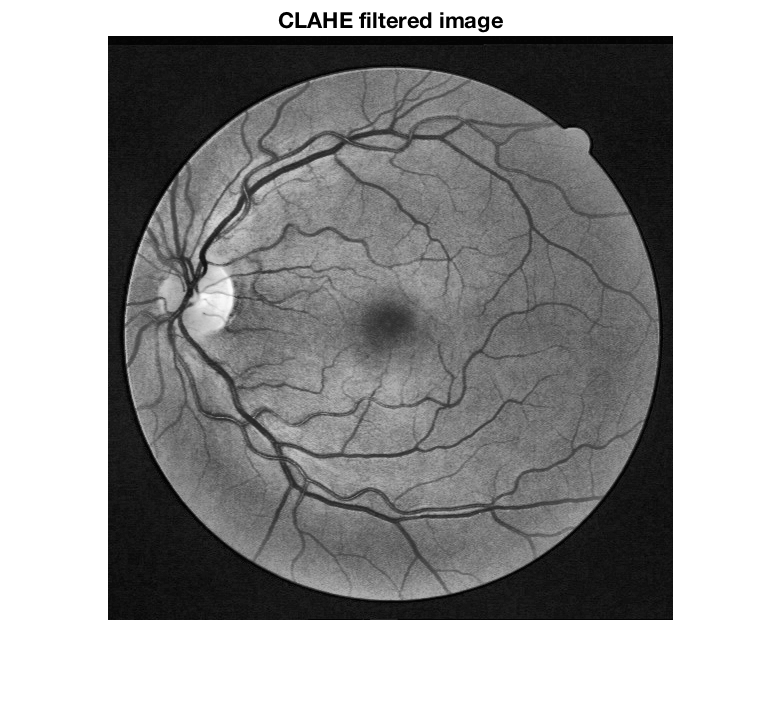

clahe = adapthisteq(green);
imshow(clahe)
title('CLAHE filtered image')

Noise reducing with median filter

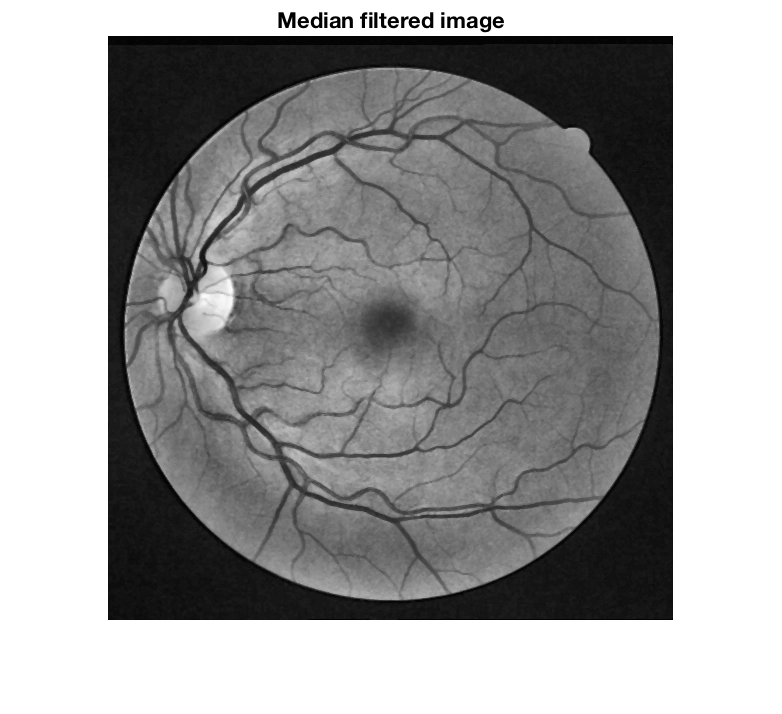

median = medfilt2(clahe);
imshow(median)
title('Median filtered image')

Use mean-C thresholding to segment blood vessels from the image

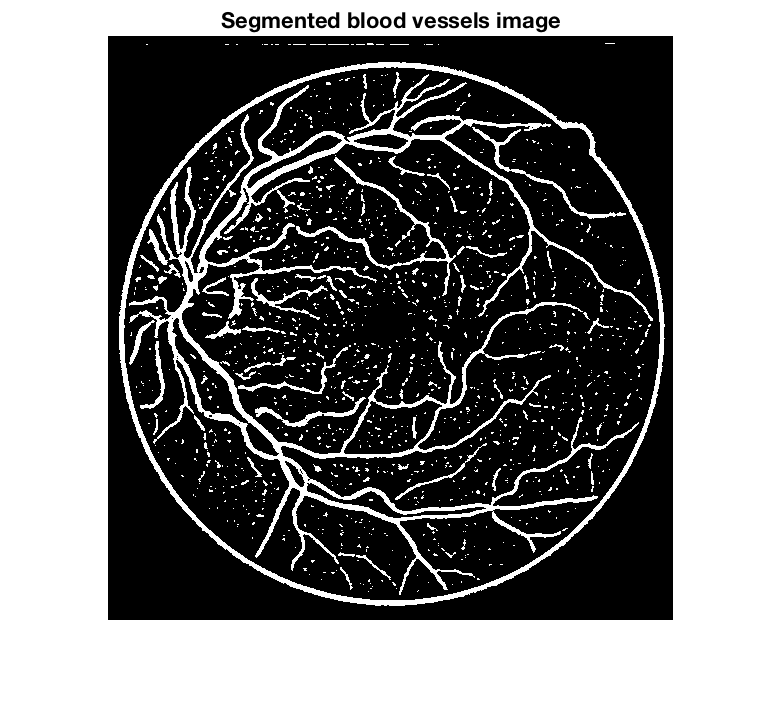

mean_c = mean_c_thresholding(median,13,0.035);
imshow(mean_c)
title('Segmented blood vessels image')

Morphological

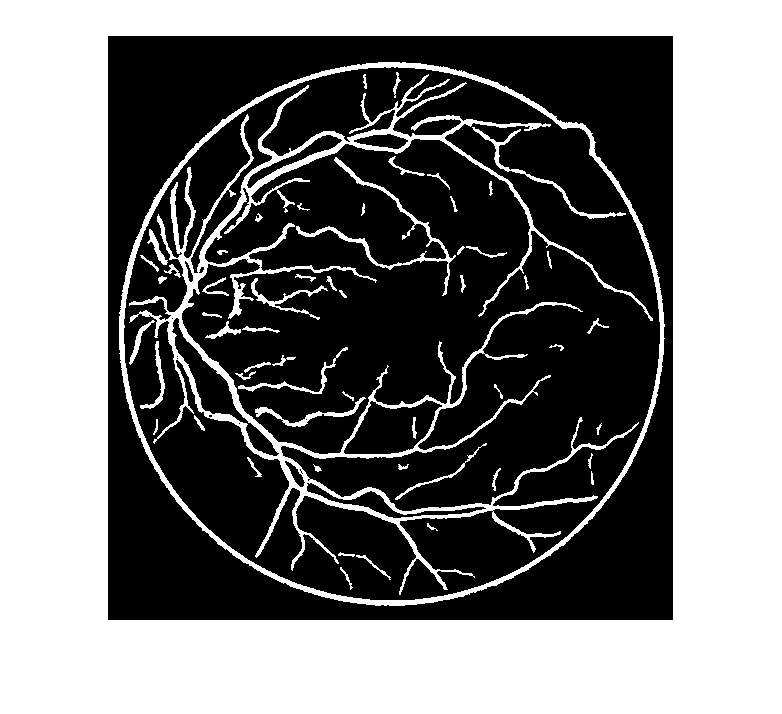

test = bwareafilt(test,[28 Inf]);
imshow(test)

TODO create binary mask image

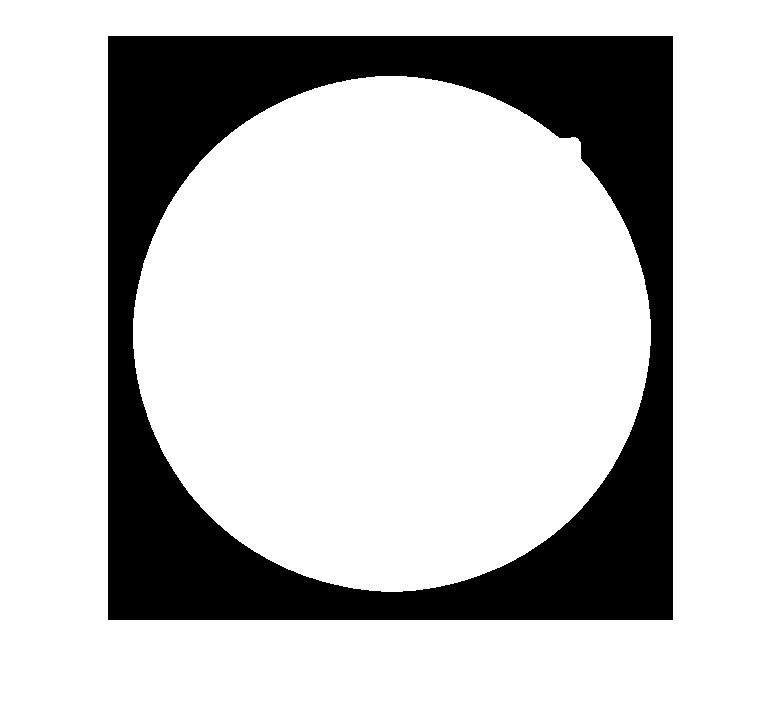

mask_thres = 10; % TODO explain this

mask = get_mask(im);

imshow(mask)

Final segmented image

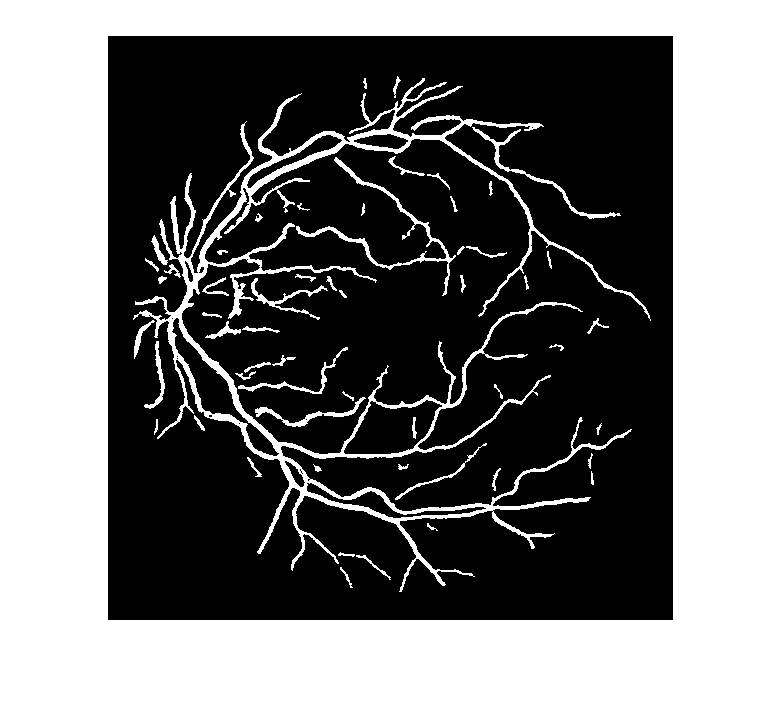

res = bitand(test,mask);
imshow(res)